# RadioShift I/Q Signal Generation Deep Dive

This Matlab Live is closely derived from the ModulationClassificationByUsingFPGAExample.mlx. The first half of this Matlab Live serves delves into preparing data for the transmitter, pulse shaping

## Acquiring Data Source and Performing Pulse Shaping by Applying Filter

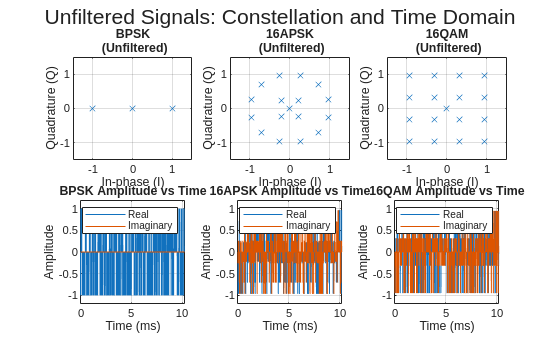

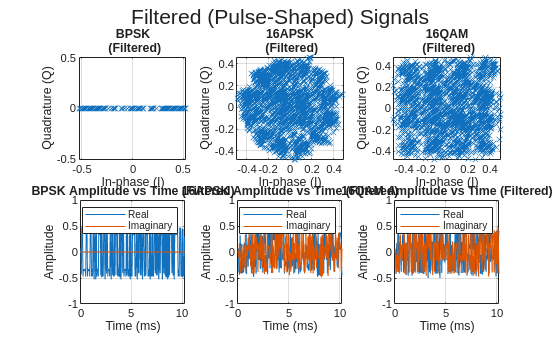


clear;
close all;
rng(12345);

% Modulation Schemes we are interested in Analyzing
Demo_Mod_Schemes = ["BPSK", "16APSK", '16QAM'];
num_Mod_Schemes = length(Demo_Mod_Schemes);

%% Directory on Lab Machine
target_directory = '/home/anagh/Repos/RadioShift/src';

if ~strcmp(pwd, target_directory)
    cd(target_directory);
end

% Setting Signal and Frame Parameters
sps = 8;                % Samples per symbol
spf = 1024;             % Samples per frame
fs = 200e3;             % Sample rate
filterCoeffs = rcosdesign(0.35, 4, sps);
x_cell = cell(num_Mod_Schemes, 1);
y_cell = cell(num_Mod_Schemes, 1);

figure(1);
sgtitle('Unfiltered Signals: Constellation and Time Domain', 'FontSize', 16);

figure(2);
sgtitle('Filtered (Pulse-Shaped) Signals', 'FontSize', 16);

for modType = 1:num_Mod_Schemes
    % Acquiring Data for each Modulation Scheme
    dataSrc = dlhdlhelperModClassGetSource(Demo_Mod_Schemes(modType), sps, (spf*2), fs);
    x_temp = dataSrc();
    x_cell{modType} = x_temp;
    
    % modulator = dlhdlhelperModClassGetModulator(Demo_Mod_Schemes(modType), sps, fs);

    
    if(modType == 1)
        syms = upsample(pskmod(x_temp,2), sps);
    elseif(modType == 2)
        syms = upsample(dvbsapskmod(x_temp, 16, 's2x'), sps);
    elseif(modType == 3)
        syms = upsample(qammod(x_temp,16,'UnitAveragePower',true), sps);
    end

    y = filter(filterCoeffs, 1, syms);

    % y = modulator(x_temp);
    y_cell{modType} = y;
    figure(1);
    % Row 1: Unfiltered
    subplot(2, 3, modType);
    plot(real(syms), imag(syms), 'x');
    xlabel('In-phase (I)');
    ylabel('Quadrature (Q)');
    title([Demo_Mod_Schemes(modType) " (Unfiltered)"]);
    %set Xlim from -3 to 3
    xlim([-1.5 1.5]);
    ylim([-1.5 1.5]);
    grid on;

    % Row 2: Time Domain of Unfiltered
    subplot(2, 3, modType + 3); % +3 for row 2, same column
    spf_plot = (length(syms));
    t = 1000*(0:spf_plot-1)/fs;
    plot(t,real(syms), '-'); grid on; axis equal; axis square
    hold on
    plot(t,imag(syms), '-'); grid on; axis equal; axis square
    hold off
    title_str = string(Demo_Mod_Schemes(modType)) + " Amplitude vs Time";
    title(title_str);
    xlim([0 max(t)]);
    ylim([-1.2 1.2]);
    xlabel('Time (ms)'); ylabel('Amplitude');
    legend("Real", "Imaginary");
    
    figure(2);
    % Row 1: Filtered (upsampled)
    subplot(2, 3, modType);
    plot(real(y), imag(y), 'x');
    xlabel('In-phase (I)');
    ylabel('Quadrature (Q)');
    title([Demo_Mod_Schemes(modType) " (Filtered)"]);
    axis equal; 
    grid on;

    subplot(2, 3, modType + 3); % +3 for row 2, same column
    spf_plot = (length(y));
    t = 1000*(0:spf_plot-1)/fs;
    plot(t,real(y), '-'); grid on; axis equal; axis square
    hold on
    plot(t,imag(y), '-'); grid on; axis equal; axis square
    hold off
    title_str = string(Demo_Mod_Schemes(modType)) + " Amplitude vs Time (Filtered)";
    title(title_str);
    xlim([0 max(t)]);
    ylim([-1 1]);
    xlabel('Time (ms)'); ylabel('Amplitude');
    legend("Real", "Imaginary");

end

## Breakdown of Pulse Shaping by Applying Filter

#### Analyzying Shape of Filter by Varying Beta, Span, and SPS

% This script compares the impulse response of a Root Raised Cosine (RRC) 
% filter by varying its key parameters: rolloff, span, and samples per symbol (sps).

%% --- Base Filter Parameters ---
base_rolloff = 0.35;
base_span    = 4;
base_sps     = 8;

%% --- Plotting and Comparison ---
figure('Position', [100, 100, 800, 900]); % Create a taller figure window
sgtitle('Impact of RRC Filter Parameters on Impulse Response', 'FontSize', 16, 'FontWeight', 'bold');

% Plot 1: Baseline Filter
subplot(4, 1, 1);
filterCoeffs1 = rcosdesign(base_rolloff, base_span, base_sps);
stem(filterCoeffs1, 'filled');
title(['Baseline: Rolloff = ' num2str(base_rolloff) ', Span = ' num2str(base_span) ', SPS = ' num2str(base_sps)]);
ylabel('Amplitude');
grid on;

% Plot 2: Increased Rolloff Factor
subplot(4, 1, 2);
increased_rolloff = 0.7;
filterCoeffs2 = rcosdesign(increased_rolloff, base_span, base_sps);
stem(filterCoeffs2, 'filled');
title(['Increased Rolloff: Rolloff = ' num2str(increased_rolloff)]);
ylabel('Amplitude');
grid on;

% Plot 3: Increased Filter Span
subplot(4, 1, 3);
increased_span = 8;
filterCoeffs3 = rcosdesign(base_rolloff, increased_span, base_sps);
stem(filterCoeffs3, 'filled');
title(['Increased Span: Span = ' num2str(increased_span)]);
ylabel('Amplitude');
grid on;

% Plot 4: Increased Samples per Symbol (SPS)
subplot(4, 1, 4);
increased_sps = 2 * base_sps;
filterCoeffs4 = rcosdesign(base_rolloff, base_span, increased_sps);
stem(filterCoeffs4, 'filled');
title(['Increased SPS: SPS = ' num2str(increased_sps)]);
xlabel('Filter Tap Index');
ylabel('Amplitude');
grid on;

## Analyzing Impact of SPS Filter Parameter on Filtered Output

%% --- Parameters ---
rolloff       = 0.35;                   % Filter rolloff factor
span          = 4;                      % Filter span in symbols
test_sequence = [1, -1, 1, 1, -1, -1];  % A simple bipolar test signal
sps_values    = [2, 8, 16];             % SPS values to analyze (Updated)

%% --- Visualization ---
figure('Position', [100, 100, 1200, 800]); % Create a larger figure window
sgtitle('Pulse Shaping Process for Varying Samples Per Symbol (sps)', 'FontSize', 16, 'FontWeight', 'bold');

num_sps = length(sps_values);

for i = 1:num_sps
    sps = sps_values(i);
    
    % --- Step 1: Upsample the discrete signal ---
    upsampled_sequence = [upsample(test_sequence, sps), zeros(1,sps*2)];

    
    % --- Step 2: Design the corresponding filter ---
    filterCoeffs = rcosdesign(rolloff, span, sps);
    
    % --- Step 3: Filter the upsampled signal ---
    filtered_output = filter(filterCoeffs, 1, upsampled_sequence);

    % === Plotting Column for current SPS ===
    
    % Plot 1: Upsampled Signal (Row 1)
    subplot(3, num_sps, i);
    stem(upsampled_sequence, 'filled', 'MarkerSize', 4);
    title(['1. Upsampled Signal (sps = ' num2str(sps) ')']);
    xlabel('Sample Index');
    ylabel('Amplitude');
    grid on;
    ylim([-1.1, 1.1]);
    xlim([0, length(test_sequence)*sps]); % Adjust x-axis to show sequence

    % Plot 2: Filter Impulse Response (Row 2)
    subplot(3, num_sps, i + num_sps);
    stem(filterCoeffs, 'filled', 'MarkerSize', 4);
    title(['2. Filter Shape (sps = ' num2str(sps) ')']);
    xlabel('Tap Index');
    ylabel('Amplitude');
    grid on;
    ylim([-0.3, 1.1]); % Consistent y-axis for filter comparison

    % Plot 3: Final Filtered Output (Row 3)
    subplot(3, num_sps, i + 2*num_sps);
    plot(filtered_output, 'LineWidth', 1.5);
    title(['3. Final Filtered Output (sps = ' num2str(sps) ')']);
    xlabel('Sample Index');
    ylabel('Amplitude');
    grid on;
    ylim([-1.5, 1.5]); % Consistent y-axis for output comparison
end



## Imposing Channel Impairment: Comparing Rayleigh vs Rician

fc = 902e6; % Carrier frequency

%% --- 2. Comparison 1: Rician vs. Rayleigh Fading ---
% Goal: Show the effect of a Line-of-Sight (LOS) path vs. no LOS path.
% We use a high SNR and zero clock offset to isolate the fading effect.
disp('Generating Figure 1: Rician vs. Rayleigh...');

Generating Figure 1: Rician vs. Rayleigh...


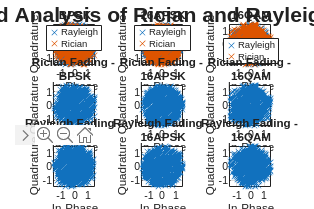


% Channel parameters for this test
fading_SNR = 30; % High SNR to see fading clearly
fading_PathDelays = [0 1.8e-6 3.4e-6]; % Multipath delays in seconds
fading_PathGains = [0 -2 -10];        % Multipath gains in dB
% fading_PathDelays = [0]; % Multipath delays in seconds
% fading_PathGains = [0]; 
fading_Doppler = 0;                  % Low Doppler for some time variation
k_factor = 10;                       % Strong LOS path for Rician

% Rician Channel (has a dominant LOS path)
ricianChannel = dlhdlhelperModClassTestChannel(...
    'SampleRate', fs, 'CenterFrequency', fc, 'ChannelType', 0, ...
    'SNR', fading_SNR, 'PathDelays', fading_PathDelays, ...
    'AveragePathGains', fading_PathGains, 'KFactor', k_factor, ...
    'MaximumDopplerShift', fading_Doppler, 'MaximumClockOffset', 0);

% Rayleigh Channel (no LOS path, just scattered reflections)
rayleighChannel = dlhdlhelperModClassTestChannel(...
    'SampleRate', fs, 'CenterFrequency', fc, 'ChannelType', 1, ...
    'SNR', fading_SNR, 'PathDelays', fading_PathDelays, ...
    'AveragePathGains', fading_PathGains, ...
    'MaximumDopplerShift', fading_Doppler, 'MaximumClockOffset', 0);

figure('Position', [100 100, 1200, 800]); % Create one larger figure
sgtitle('Combined Analysis of Rician and Rayleigh Fading', 'FontSize', 16, 'FontWeight', 'bold');

for modType = 1:num_Mod_Schemes
    % Pass the same clean signal through both channels
    rician_frame = ricianChannel(y_cell{modType});
    rayleigh_frame = rayleighChannel(y_cell{modType});
    ricianSignal = dlhdlhelperModClassFrameGenerator(rician_frame, spf, spf, 50, sps);
    rayleighSignal = dlhdlhelperModClassFrameGenerator(rayleigh_frame, spf, spf, 50, sps);
    
    subplot(3, 3, modType);
    plot(real(rayleighSignal), imag(rayleighSignal), 'x');
    hold on;
    plot(real(ricianSignal), imag(ricianSignal), 'x');
    hold off;
    title(Demo_Mod_Schemes(modType));
    xlabel('In-Phase'); ylabel('Quadrature');
    legend('Rayleigh', 'Rician', 'Location', 'best');
    axis square; grid on; axis([-1.5 1.5 -1.5 1.5]);

        % --- Top Row: Rician Channel Plots ---
    subplot(3, 3, modType + num_Mod_Schemes);
    plot(real(ricianSignal), imag(ricianSignal), 'x'); 
    title(['Rician Fading - ' Demo_Mod_Schemes(modType)]);
    xlabel('In-Phase'); 
    ylabel('Quadrature');
    axis square; grid on;
    axis square; grid on; axis([-1.5 1.5 -1.5 1.5]);

    % --- Bottom Row: Rayleigh Channel Plots ---
    subplot(3, 3, modType + 2*num_Mod_Schemes);
    plot(real(rayleighSignal), imag(rayleighSignal), 'x');
    title(['Rayleigh Fading - ' Demo_Mod_Schemes(modType)]);
    xlabel('In-Phase'); 
    ylabel('Quadrature');
    axis square; grid on;
    axis([-1.5 1.5 -1.5 1.5]);
end

## Imposing Channel Impairment: Comparing Impact of Clock Offset


%% --- 3. Comparison 2: Impact of Clock Offset (PPM) ---
% Goal: Show how clock offset causes constellation rotation.
% We use a simple AWGN channel (no fading) and high SNR to isolate rotation.
%% --- Comparison: Impact of Clock Offset (PPM) ---
disp('Generating combined figure for Clock Offset analysis...');

Generating combined figure for Clock Offset analysis...


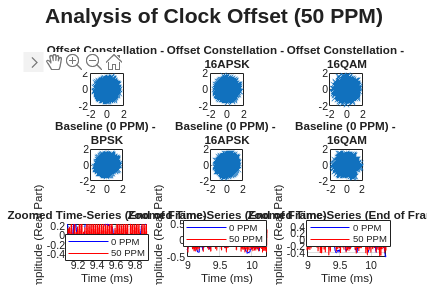


% Channel parameters for this test
ppm_SNR = 30; % Very high SNR for clean points
ppm_val = 50; % 50 PPM offset

% --- Channel Definitions ---
% Baseline Channel (No Clock Offset) - effectively a simple AWGN channel
baselineChan_ppm = dlhdlhelperModClassTestChannel(...
    'SampleRate', fs, 'CenterFrequency', fc, 'ChannelType', 0, ...
    'SNR', ppm_SNR, 'PathDelays', 0, 'AveragePathGains', 0, 'KFactor', 1e6, ...
    'MaximumDopplerShift', 0, 'MaximumClockOffset', 0);

% Impaired Channel (with Clock Offset)
ppmChan = dlhdlhelperModClassTestChannel(...
    'SampleRate', fs, 'CenterFrequency', fc, 'ChannelType', 0, ...
    'SNR', ppm_SNR, 'PathDelays', 0, 'AveragePathGains', 0, 'KFactor', 1e6, ...
    'MaximumDopplerShift', 0, 'MaximumClockOffset', ppm_val, 'HardSetOffsetPPM', 1);

%% --- Create the Combined 3x3 Figure ---
figure('Position', [100 100, 1200, 800]);
sgtitle(['Analysis of Clock Offset (' num2str(ppm_val) ' PPM)'], 'FontSize', 16, 'FontWeight', 'bold');

for modType = 1:num_Mod_Schemes
    % Generate the raw frames by passing signals through the channels
    baseline_frame = baselineChan_ppm(y_cell{modType});
    offset_frame = ppmChan(y_cell{modType});
    
    % Use the helper function to get the final signal frames for constellations
    baselineSignal_const = dlhdlhelperModClassFrameGenerator(baseline_frame, spf, spf, 50, sps);
    offsetSignal_const = dlhdlhelperModClassFrameGenerator(offset_frame, spf, spf, 50, sps);
    
    % --- Row 1: Overlaid Constellations (shows rotation) ---
    subplot(3, 3, modType);
    plot(real(offsetSignal_const), imag(offsetSignal_const), 'x');
    title(['Offset Constellation - ' Demo_Mod_Schemes(modType)]);
    axis square; grid on;
    xlim([-2 2]);
    ylim([-2 2]);

    % --- Row 2: Baseline Constellations (clean reference) ---
    subplot(3, 3, modType + num_Mod_Schemes);
    plot(real((baselineSignal_const)), imag((baselineSignal_const)),'x');
    title(['Baseline (0 PPM) - ' Demo_Mod_Schemes(modType)]);
    axis square; grid on; axis([-1.5 1.5 -1.5 1.5]);
    xlim([-2 2]);
    ylim([-2 2]);
    % --- Row 3: Zoomed Time-Series Comparison (shows drift) ---
    subplot(3, 3, modType + 2*num_Mod_Schemes);
    
    % Create a time vector based on the raw frame length and sample rate
    num_samples = length(baseline_frame);
    t = (0:num_samples-1) / fs * 1000; % Time in milliseconds
    
    plot(t, real(baseline_frame), 'b-');
    hold on;
    plot(t, real(offset_frame), 'r-');
    hold off;
    
    title('Zoomed Time-Series (End of Frame)');
    xlabel('Time (ms)');
    ylabel('Amplitude (Real Part)');
    legend('0 PPM', [num2str(ppm_val) ' PPM'] ,'Location','best');
    grid on;
    
    % Zoom in on the last 250 samples to see the accumulated drift
    zoom_samples = 250;
    if num_samples > zoom_samples
        xlim([t(end-zoom_samples) t(end)]);
    end
end

## Imposing Channel Impairment: Comparing Impact of SNR

%% --- 4. Comparison 3: Impact of SNR ---
% Goal: Show how noise spreads the constellation points.
% We use a simple AWGN channel (no fading/offset) to isolate noise.
disp('Generating Figure 3: Impact of SNR...');

Generating Figure 3: Impact of SNR...


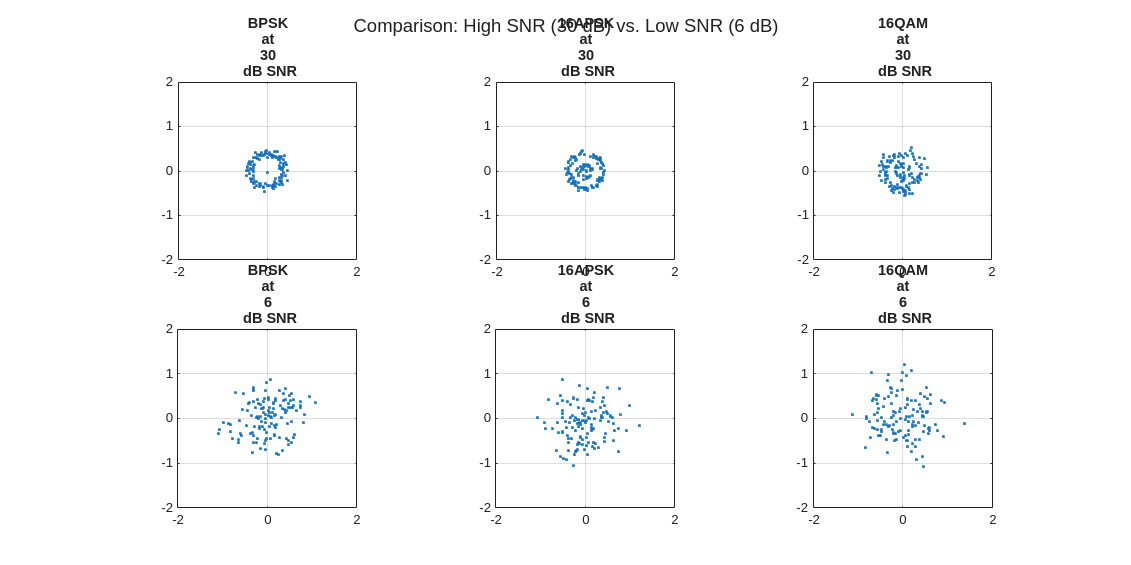


snr_high = 30; % High SNR
snr_low = 6;   % Low SNR

% High SNR Channel
highSnrChan = dlhdlhelperModClassTestChannel(...
    'SampleRate', fs, 'CenterFrequency', fc, 'ChannelType', 0, ...
    'SNR', snr_high, 'PathDelays', 0, 'AveragePathGains', 0, 'KFactor', 1e6, ...
    'MaximumDopplerShift', 0, 'MaximumClockOffset', 0);

% Low SNR Channel
lowSnrChan = dlhdlhelperModClassTestChannel(...
    'SampleRate', fs, 'CenterFrequency', fc, 'ChannelType', 0, ...
    'SNR', snr_low, 'PathDelays', 0, 'AveragePathGains', 0, 'KFactor', 1e6, ...
    'MaximumDopplerShift', 0, 'MaximumClockOffset', 0);
    
figure('Position', [300 300 1200 600]);
sgtitle(['Comparison: High SNR (' num2str(snr_high) ' dB) vs. Low SNR (' num2str(snr_low) ' dB)'], 'FontSize', 14);

for modType = 1:num_Mod_Schemes
    highSnrSignal = highSnrChan(y_cell{modType});
    lowSnrSignal = lowSnrChan(y_cell{modType});

    % Plot High SNR in the top row
    subplot(2, 3, modType);
    plot(real(downsample(highSnrSignal,sps)), imag(downsample(highSnrSignal,sps)), '.');
    title([Demo_Mod_Schemes(modType) ' at ' num2str(snr_high) ' dB SNR']);
    axis([-2 2 -2 2]); axis square; grid on;

    % Plot Low SNR in the bottom row
    subplot(2, 3, modType + 3);
    plot(real(downsample(lowSnrSignal,sps)), imag(downsample(lowSnrSignal,sps)), '.');
    title([Demo_Mod_Schemes(modType) ' at ' num2str(snr_low) ' dB SNR']);
    axis([-2 2 -2 2]); axis square; grid on;
end

disp('Done.');

Done.
